# **MATLAB ASSIGNMENT - 1**

#### **Table of Contents**

- Image reading

- Image displaying

- Applying graysacle

- Displaying grayscale image

- Applying filters

- displaying result

- Comparing the original image and filtered image

- Saving result

# Reading an image into workspace variable

A = imread("insta.jpg"); %reading image

# Displaying the image

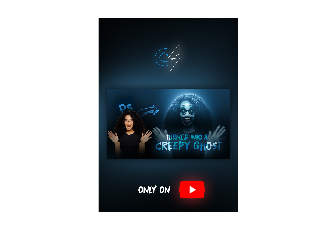

imshow(A) % displaying the image

# Applying grayscaling 

Grayscale means the images will turn into balck and white which are commonly shades of gray  

image_filter = im2gray(A); % applying grayscale to the image

# Displaying the grayscaling image

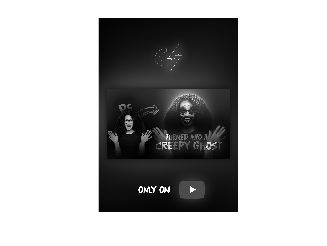

imshow(image_filter) % displaying grayscale image

# Applying filters to the image

F = fspecial("average",32); % averaging pixels of image by 20, 20
G = fspecial("gaussian",35,0.9);
Ifltr = imfilter(image_filter,F); % applying the image filter of F to our image(A)

**Average Filter**

The average filter computes an average to every value of each vector for the input vectors

**Gaussian Filter**

The guassian filter reduces the noise and disturbances from the image.

# Display the result

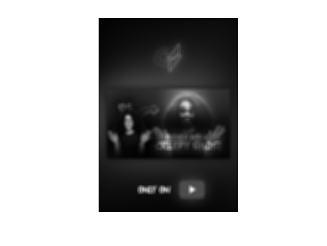

imshow(Ifltr) % displaying the image after applying filter

# Comparing the original image and filtered image

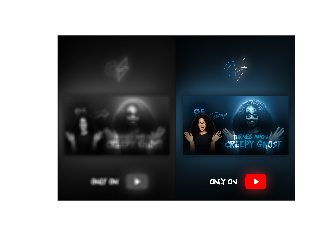

imshowpair(Ifltr,A,"montage") % displaying original image, filtered image side by side(montage)

# Saving the image to a .png file

imwrite(Ifltr,'final.png')